# Visualize Vector Fields Using Tube Volumes

streamtube draws 3D tube volumes from provided vector volume data. The width of the tubes is proportional to the normalized divergence of the vector field.

## Load Data to Plot

Load the built in wind vector field and set a volume of points for the stream ribbon to be evaluated at.

load wind
[sx,sy,sz] = meshgrid(80,20:10:50,0:5:15);

## Basic Streamtube Plot

Use the `streamtube` function to indicate flow in the wind data set. The inputs include the coordinates, vector field components, and starting location for the stream tubes. 

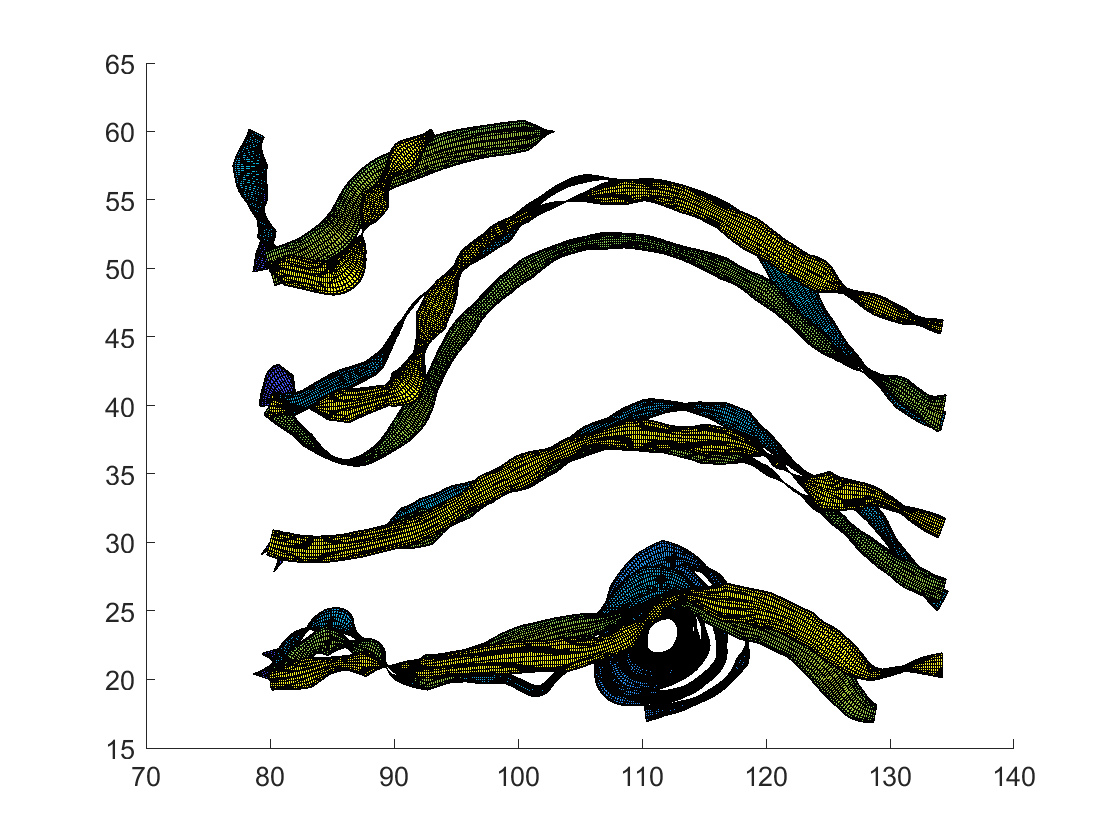

figure

st = streamtube(x,y,z,u,v,w,sx,sy,sz);

## Customizations

### Specify Viewing Options

Viewing parameters for the plot can be adjusted to improve readability. An isometric view can be positioned programmatically through the `view` command. Shading and lighting parameters can also be manipulated to provide optimal visibility. A light source is specified to the right with gouraud lighting options and interpolated shading.

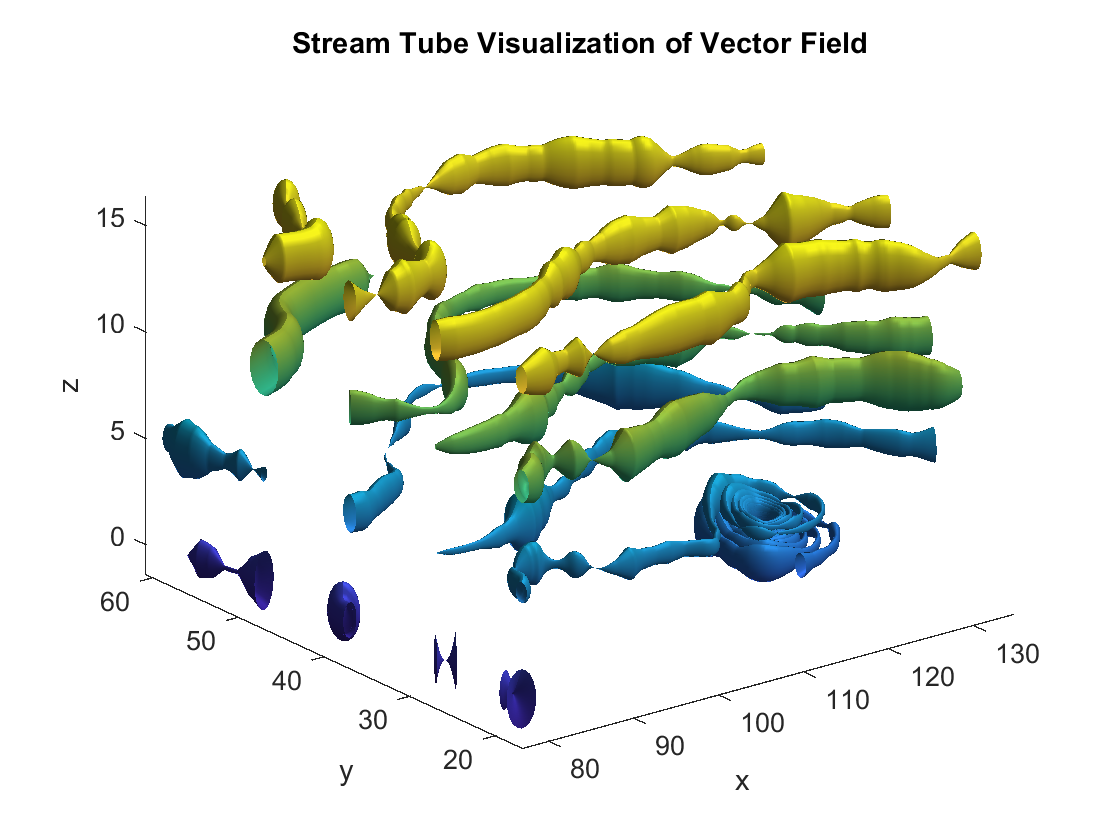

view(3);                       
axis tight   
shading interp
camlight; 
lighting gouraud;

title('Stream Tube Visualization of Vector Field')
xlabel('x')
ylabel('y')
zlabel('z')

## Additional Information

### Get All Streamtube Properties

Graphics objects in MATLAB have many properties. To see all the properties of a streamtube, uncomment the following code

% get(st)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[streamtube](https://www.mathworks.com/help/matlab/ref/streamtube.html)